# Reference Tracking and Disturbance Rejection using Vanilla MPC 

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction 

So far we have only dealt with a very special class of control problem, i.e. regulation at an equilibrium point when the system state is perturbed. While this helped us to get many theoretical insights into development of MPC, the regulation problem that we have considered has a very limited use in practice. Most of the real systems require operation at changing or time varying reference state (setpoints).  Some examples are

- Car speed changes with traffic → speed reference changes.

- Continuous Annealing Furnace in a steel plant: Furnace temperature varies with recipe → temperature setpoints change for different grades of steel 

- Robot arm moves to multiple positions → trajectory changes.

In such cases, MPC must continuously **track new targets** while maintaining smooth and optimal transitions. To make these formulations applicable in practice, we include servo capabilities in the MPC formulation. 

The other important requirement is ability to deal with the unmeasured disturbances and/or model plant mismatch. Note that that we have re-formulated the original control problem using a linear perturbation model and this itself results in model plant mismatch. Also, real systems are always subject to unmeasured time varying disturbances and the controller needs to respond to ensure that the desired control goals are met. Here are some examples of unmeasured disturbances:

- Autonomous car control: wind gusts, terrain changes (up-hill or down-hill travel) 

- Continuous Annealing Furnace in a steel plant: changes in fuel quality, changes in characteristics of the steel (i.e. treatment of different grades of steel) 

- Building Temperature Control: Changes in heat transfer from walls due to changes in the atmospheric conditions

Thus, the basic MPC formulation that we developed in the previous lesson now needs to me made ready for the real world applications. On this backdrop, the **learning objectives** of this lesson are as follows:

- Modify the vanilla MPC formulation to incorporate servo control feature

- Modify the vanilla MPC formulation to deal with unmeasured disturbances and model plant mismatch 

## Reference Tracking Control Using MPC

In this section we first introduce tracking of a fixed non-zero reference or setpoint using MPC. We then move to tracking of time varying reference. 

### Tracking Fixed non-zero Setpoint

To deal with reference tracking problems, we now modify the model used in MPC by including the controlled outputs, i.e. the system/plant is governed by 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)\;
\end{array}$  ------(1) 

where $x\in R^n ,u\in R^m \;\textrm{and}\;y\in R^l$.  Till now we only examined the case of controlling the system at the origin, i.e. $y\left(k\right)\to \bar{0} \;\textrm{as}\;k\to \infty$. Now consider a scenario when the system has settled at the origin and we intend to move the system operation to $y\left(k\right)\to r\not= \bar{0} \;\textrm{as}\;k\to \infty$ where $r\in R^l$represents some new desired output (setpoint or reverence output). When the system outputs settle at $y_s =y\left(\infty \right)\to r\;$, the system states have need to move away from the origin to another equilibrium point, say $\left(x_s ,u_s \right)$ such that the following set of equations hold at the new equilibrium 

$\begin{array}{l}
x_s =\Phi x_s +\Gamma u_s \\
y_s =C\;x_s =r
\end{array}$  ------ (2) 

When the number of inputs is either equal to the number of outputs or more than the number of outputs, it is possible to find $\left(x_s ,u_s \right)$ such that achieves the desired output. When the system is asymptotically stable and *m = l, *we can find $\left(x_s ,u_s \right)$ as follows 

$\begin{array}{l}
x_s ={\left(I-\Phi \right)}^{-1} \Gamma u_s \\
u_s ={\left(C{\left(I-\Phi \right)}^{-1} \Gamma \right)}^{-1} \;r={\left({\mathrm{K}}_u \right)}^{-1} r
\end{array}$  ------(3) 

Here it is assumed that the steady state gain matrix ${\mathrm{K}}_u =\;C{\left(I-\Phi \right)}^{-1} \Gamma$ is invertible. Given these new target states, we can modify the vanilla MPC formulation as follows: 

$J\left\lbrack x\left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|z\left(k+p\right)-x_s \right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j\right)-x_s \right\|}^2 }_{W_x } +{{\left\|u\left(k+j|k\right)-u_s \right\|}^2 }_{W_u } \right\rbrace$  ------(4)

Thus, the regulatory MPC at instant $k$ is formulated as follows


$$\;$$
  
$$U_f^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_f \left(k\right)} \;\;\;\left\lbrack J\left(x\left(k\right),U_f \left(k\right)\right)\right\rbrack$$
   

Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)\\
\textrm{for}\;j=0,1,\ldotp \ldotp \ldotp ,p-1\;\textrm{with}\;z\left(k\right)=x\left(k\right)
\end{array}$   ------(5) 

     $u_L \le u\left(k+j|k\right)\le u_H$   for$j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$   ------(6) 

Recall that we have arranged the model equations as follows for the purpose of formulating a QP 

$Z_p \left(k\right)=S_x x\left(k\right)+S_u U_f \left(k\right)$  -----(7) 

Defining stacked target vectors 

$U_s ={\left\lbrack u_s^T \;{\;\;u}_s^T \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp u_s^T \right\rbrack }^T$----------(8)

$X_s ={\left\lbrack x_s^T \;{\;\;x}_s^T \;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp x_s^T \right\rbrack }^T$------------(9)

the cost function (4) can be expressed as 

$\varphi_{\textrm{tracking}} ={\left(Z_p \left(k\right)-X_s \right)}^T {\mathbf{W}}_X \left(Z_p \left(k\right)-X_s \right)+{\left(U_f \left(k\right)-U_s \right)}^T {\mathbf{W}}_U \left(U_f \left(k\right)-U_s \right)$ -----(10)

From the viewpoint of optimization terms ${\left(X_s \right)}^T {\mathbf{W}}_X \left(X_s \right)$ and ${\left(U_s \right)}^T {\mathbf{W}}_X \left(U_s \right)$ can be ignored. With reference to the regulatory objective at the origin, two new terms that appear in the tracking objective are $-2\;{\left(U_s \right)}^T {\mathbf{W}}_U \left(U_f \left(k\right)\right)$ and 


$${-2\left(X_s \right)}^T {\mathbf{W}}_X \left(Z_p \left(k\right)\right)=-{2\left(X_s \right)}^T {\mathbf{W}}_X \left(S_x x\left(k\right)+S_u U_f \left(k\right)\right)$$


From the viewpoint of QP formulation, $-{2\left(X_s \right)}^T {\mathbf{W}}_X \left(S_x x\left(k\right)\right)$ can be ignored and we only need to account for $-{2\left(X_s \right)}^T {\mathbf{W}}_X \left(S_u U_f \left(k\right)\right)$. Defining stacked matrices

 
$${\mathbf{I}}_X =\left\lbrack \begin{array}{c}
I_{n\times n} \\
\ldotp \ldotp \ldotp \ldotp \\
I_{n\times n} 
\end{array}\right\rbrack \;\;\;\;\textrm{and}\;{\mathbf{I}}_U =\left\lbrack \begin{array}{c}
I_{m\times m} \\
\ldotp \ldotp \ldotp \ldotp \\
I_{m\times m} 
\end{array}\right\rbrack$$


Thus, the cost function of the QP formulation for solving the tracking control problem is 

$\varphi_{\textrm{tracking}} \;=\frac{1}{2}{{\;U}_f \left(k\right)}^T \;\mathbf{H}\;U_f \left(k\right)+{F\left(k\right)}^T U_f \left(k\right)$  -----(11a) 

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\mathbf{H}=2\left({S_u }^T {\mathbf{W}}_X S_u +{\mathbf{W}}_U \right)\;\\
\textrm{and}\;\;F\left(k\right)=2\left({{S_u }^T \mathbf{W}}_X S_x \right)\;x\left(k\right)-2\;\left({\mathbf{W}}_U {\mathbf{I}}_U \right)u_s -{2\left(S_u \right)}^T {\mathbf{W}}_X \left({\mathbf{I}}_X \right)x_s 
\end{array}$ ------(11b)

### Target Tracking Control of Quadruple Tank Process

Let us see how this simple target tracking works for the quadruple tank system. Let is assume that levels $h_1 \;\textrm{and}\;h_2$ are to be controlled at some desired setpoints. Here we examine the scenario of changing the setpoints.  In this exercise we will observe the effect of MPC tuning parameters on the controller performance.

 
clear all 
close all
global QTank 

Set_Graphics_Parameters ;   % This script file sets font size and line thickness for figures 

**Task 1**: Recall that Q Tank process has two steady state operating points. Select the operating point for Q Tank process.  This will load quadruple tank parameters and steady state corresponding to the selected operating point

operating_pt=2;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

% Initialization of linear discrete time model for plant simulation 

phy = QTank.phy ;
gam = QTank.gama_u  ;
gam_d = QTank.gama_d  ;
[n_st,n_ip] = size(gam) ;
C_mat = [ 1 0 0 0 ; 0 1 0 0] ;  % Levels are assume to be directly measured 
[n_op, nx ] = size(C_mat)  ;         
[n_st,n_ip] = size(gam) ;

**Task 2**: Set the simulation run time N to 301.

N = 301 ;      % Simulation run time
% Initialization of Internal model for MPC 

mpc.phy = phy ;   
mpc.gam = gam ; 
mpc.C_mat = C_mat ; 
[mpc.n_st,mpc.n_ip] = size(mpc.gam) ;
[mpc.n_op, nx] = size(mpc.C_mat) ; 


**Effect of MPC Tuning Parameters**

**Task 3: **Set the prediction horizon n_pred to interval >= 50**.**

mpc.n_pred =50; 

**Task 4:** We have created variables ${\textrm{mpc}\ldotp W}_x$, the **State Weighting Matrix  **and ${\textrm{mpc}\ldotp W}_u$, the **Input Weighting Matrix**.  

 $W_x =\left\lbrack \begin{array}{cccc}
\alpha_1  & 0 & 0 & 0\\
0 & \alpha_2  & 0 & 0\\
0 & 0 & \alpha_3  & 0\\
0 & 0 & 0 & \alpha_4 
\end{array}\right\rbrack$  and  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$

alpha(1) =2;  alpha(2) = 10;
alpha(3) =2;  alpha(4) = 2; 

State weighting matrix


disp('State weighting matrix')
mpc.Wx= diag(alpha );

Input weighting matrix


disp('Input weighting matrix')
beta(1) =2;  beta(2) =1;
mpc.Wu= diag(beta); 

For the quadruple tank system input voltages are bound between 0 and 5 Volts. Thus, bounds on perturbation inputs, with reference to $U_s ={\left\lbrack \begin{array}{cc}
3 & 3
\end{array}\right\rbrack }^T$ for minimum phase system can be defined as follows 

$u_H =\left\lbrack \begin{array}{c}
5\\
5
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack \;$  and  $u_L =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-3\\
-3
\end{array}\right\rbrack$

We have written a code that  generates matrices needed for specifying input constraints.  

mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] 
mpc.deluL = [] ; mpc.deluH = [] ; 

**Generation of  QP matrices**

Note: A function (Gen_QP_Matrices_Tracking) is used to generate QP matrices.

% Generate QP matrices 
[mpc] = Gen_QP_Matrices_Tracking( mpc ) ;

**Closed loop simulations using QP-LMPC under ideal conditions**

We have generated target states for different setpoint changes as given in equation (3). The steady state gain matrix is given by  $G=\;C{\left(I-\Phi \right)}^{-1} \Gamma$ as seen earlier

mpc.xkhat = zeros(mpc.n_st,N);
mpc.xs_0 = zeros(mpc.n_st,1) ;
mpc.us_0 = zeros(n_ip,1) ;
rk_1 = [3 -4 ]' ;
mpc.us_1 = inv(mpc.Gain_ss) * rk_1 ;
mpc.xs_1= inv(eye(mpc.n_st) - mpc.phy) * mpc.gam * mpc.us_1 ;
rk_2 = [-3 3.5 ]' ;
mpc.us_2 = inv(mpc.Gain_ss) * rk_2 ;
mpc.xs_2= inv(eye(mpc.n_st) - mpc.phy) * mpc.gam * mpc.us_2 ;

xk = zeros(n_st,N);
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N);
yk(:,1) = C_mat * xk(:,1) ; 
setpt_k = zeros(n_op,N); 
time_log = zeros(N,1);  % preallocate
options=optimoptions('quadprog', 'display', 'off');

**Controller Implementation**

Optimal controller output is obtained using MATLAB function [quadprog](https://in.mathworks.com/help/optim/ug/quadprog.html). [`x`](https://in.mathworks.com/help/optim/ug/quadprog.html#mw_4fdf75e1-35ab-4c9d-aaf4-c81f677d0f62)` = quadprog(`[`H`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1-H)`,`[`f`](https://in.mathworks.com/help/optim/ug/quadprog.html#d126e155087)`,`[`A`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1_sep_shared-A)`,`[`b`](https://in.mathworks.com/help/optim/ug/quadprog.html#bssh6y6-1_sep_shared-b)`,[],[],[],[],[],options )` as done in earlier exercises.  Controller calculations at instant $k$ are done assuming state vector is perfectly measured

Quadruple tank Plant Simulation from$k\;\textrm{to}\;k+1$is done using discrete linear model $x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$. It is assumed that plant state is perfectly measured.

for k = 1:N-1
    kT(k) = (k-1);

    % Controller calculations at instant k assuming state vector is perfectly measured
    if ( k < 50 )
        mpc.xs_k = mpc.xs_0 ; mpc.us_k = mpc.us_0 ;
    elseif (k >= 50 ) && (k< 175)
        mpc.xs_k = mpc.xs_1 ; mpc.us_k = mpc.us_1 ;  % Introduce setpoint change at k = 50
    else
        mpc.xs_k = mpc.xs_2 ; mpc.us_k = mpc.us_2 ;  % Introduce another setpoint change at k = 150
    end
    setpt_k(:,k) = C_mat * mpc.xs_k ;
    tic
    b_vec = mpc.F_vec ;
    mpc.xk = xk(:,k) ;   % Plant state is perfectly measured
    Fk_vec = mpc.F_mat*mpc.xk - 2 * mpc.WU_mat * mpc.Iu_mat * mpc.us_k  - 2 * mpc.Su_mat' * mpc.WX_mat * mpc.Ix_mat * mpc.xs_k ;
    [Uf_k,fval] = quadprog(mpc.H_mat, Fk_vec, mpc.A_mat, b_vec,[],[],[],[],[],options )  ;
    mpc.uk = Uf_k(1:n_ip) ;  % Implement only optimal u(k)
    time_log(k) = toc;


Quadruple tank Plant Simulation from$k\;\textrm{to}\;k+1$is done using discrete linear model $x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$. It is assumed that plant state is perfectly measured.

    uk(:,k) = mpc.uk ;
    xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) ;
end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;
setpt_k(:,N) = C_mat * mpc.xs_k ;

**LMPC-QP Controller Performance: Target Tracking**

**Task 5:** Note down the average time required for controller implementation using QP solver,(**avg_time_TLMPC_QP**). Also note down the cost function (**fval_TLMPC_QP**).

The calculations are done as shown in the [previous lesson](matlab:open('./L1_LQOC_To_MPC.mlx'))

fval_TLMPC_QP = 0 ;
for k = 1:N-1
    fval_TLMPC_QP=fval_TLMPC_QP+ xk(:,k)' * mpc.Wx* xk(:,k) ;
    fval_TLMPC_QP=fval_TLMPC_QP+uk(:,k)' * mpc.Wu* uk(:,k) ;
end
avg_time_TLMPC_QP = mean(time_log);

Average computation time TLMPC-QP: 0.0024202 s


disp(['Average computation time TLMPC-QP: ', num2str(avg_time_TLMPC_QP), ' s']);

TLMPC-QP Cost Function: 60574.9748


disp(['TLMPC-QP Cost Function: ', num2str(fval_TLMPC_QP)]);

**Simulation Results**

Now observe the simulation results that show the state and input profiles plotted against time. Observe that the states are driven to the desired steady state values, irrespective of the initial condition.The controller outputs are within the specified upper and lower limits.

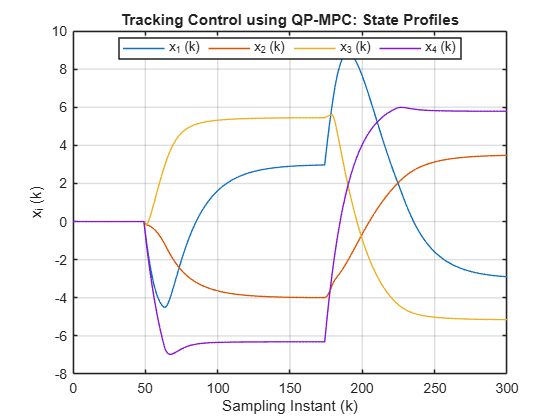

figure(1), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)', 'Orientation','horizontal','Location','Best')
title('Tracking Control using QP-MPC: State Profiles')

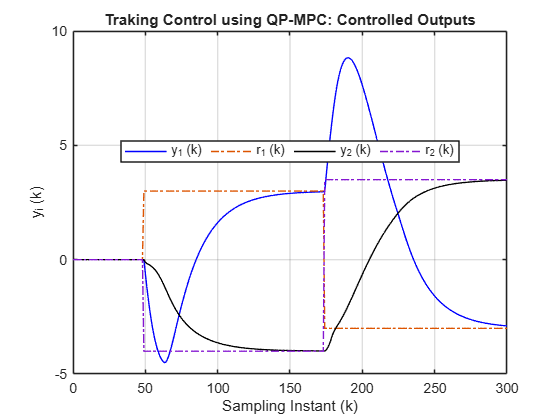

figure(2), plot(kT, yk(1,:), 'b',  kT, setpt_k(1,:), '-.', kT, yk(2,:), 'k', kT, setpt_k(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('y_i (k)')
legend('y_1 (k)', 'r_1 (k)', 'y_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best') 
title('Traking Control using QP-MPC: Controlled Outputs')

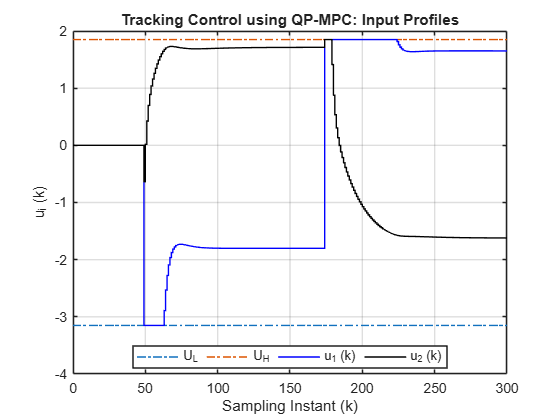

U_mimits = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;
figure(3), stairs(kT, U_mimits, '-.', 'LineWidth',1), grid
hold on 
 stairs(kT, uk(1,:)', 'b','LineWidth',1)
 stairs(kT, uk(2,:)', 'k','LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_i (k)')
title('Tracking Control using QP-MPC: Input Profiles')
legend('U_L', 'U_H', 'u_1 (k)', 'u_2 (k)','Orientation','horizontal','Location','Best')

**Task 6: **Go to Task 3 and try changing the prediction horizon. Observe the effect on servo response by increasing or decreasing the prediction horizon. 

**Task 7: **Go to Task 4 and try changing the weighting matrices. How does the response change if all weights in $W_x$ are equal? What happens if only one weight in $W_x$ is say 100 times higher than the rest three?  What do you observe when input weights in $W_u$ are unequal? 

**Task 8:** Now change the operating point and again observe the results.

## Tracking Time Varying Setpoints 

Many real world applications involve time varying setpoints. In the previous sub-section we introduced setpoint change as a step changes. This leads to sudden changes in the manipulated inputs. To avoid such abrupt changes, it is possible to generated a gradually setpoint trajectory by introducing a unity gain setpoint filter as follows (see Appendix for details): 

$r_f \left(k+1\right)=\Phi_r r_f \left(k\right)+\left({I-\Phi }_r \right)\;r\left(k\right)$  ------(12)

Here $\Phi_r$  is a diagonal matrix with diagonal element ${0\le \alpha }_i <1$. Use of such filtered setpoint trajectory results in time varying target states 

$\begin{array}{l}
x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \Gamma u_s \left(k\right)\\
u_s \left(k\right)={\left(G\right)}^{-1} \;r_f \left(k\right)
\end{array}$ ------(13)

where $G=\;C{\left(I-\Phi \right)}^{-1} \Gamma$. These simple calculations can be used when $u_s \left(k\right)$ stays within the input bounds. If $u_s \left(k\right)$ estimated using (13) violate input bounds, then the target state calculations can be carried out by solving the following constrained optimization problem 

$\min_{u_s \left(k\right)} \left\lbrace {\left(r_f \left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r_f \left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(14)

subject to,

$y_s \left(k\right)=K_u u_s \left(k\right)$ ------(15) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (16)

Here, $W_{\textrm{ys}}$ is a positive definite (typically diagonal) weighting matrix.  Note that this optimization formulation needs to be used even when when the number of controlled outputs is not equal to the number of manipulated inputs. With the introduction of time varying target states, the MPC loss function is modified as follows 

$J\left\lbrack x\left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|z\left(k+p\right)-x_s \left(k\right)\right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j\right)-x_s \left(k\right)\right\|}^2 }_{W_x } +{{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u } \right\rbrace$  ------(17) 

Let us investigate how filtered setpoint trajectories alter the closed loop behavior of the quadruple tank system. The steps performed upto steady state gain computation are same as the previous exercise.

### **Servo Control using QP-LMPC under ideal conditions**

Controller calculations at instant $k$ assuming state vector is perfectly measured . A time varying reference input signal is generated such that initially it is set to zero for both the outputs.  Then the vector is changed from it's initial value to $r\left(k\right)=\left\lbrack 3\;\;-4\right\rbrack$ in between $50<k<175$and then subsequently it is changed to $r\left(k\right)=\left\lbrack -3\;\;3\ldotp 5\right\rbrack$. Set point is also filtered as


$$r_f \left(k+1\right)=\Phi_r r_f \left(k\right)+\left(I-\Phi_r \right)r\left(k\right)$$


In this section, we will observe the effect of this set point filter on the controller performance

 
clear all 
close all
global QTank 

Set_Graphics_Parameters ;   % This script file sets font size and line thickness for figures 

**Task 1**: Select the operating point for Q Tank process.  

operating_pt=2;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

% Initialization of linear discrete time model for plant simulation 

phy = QTank.phy ;
gam = QTank.gama_u  ;
gam_d = QTank.gama_d  ;
[n_st,n_ip] = size(gam) ;
C_mat = [ 1 0 0 0 ; 0 1 0 0] ;  % Levels 1 and 2 are assume to be directly measured 
[n_op, nx ] = size(C_mat)  ;         
[n_st,n_ip] = size(gam) ;

We have set the simulation run time N to 301.

N = 301 ;      % Simulation run time
% Initialization of Internal model for MPC 

mpc.phy = phy ;   
mpc.gam = gam ; 
mpc.C_mat = C_mat ; 
[mpc.n_st,mpc.n_ip] = size(mpc.gam) ;
[mpc.n_op, nx] = size(mpc.C_mat) ; 


**MPC Tuning Parameters**

We have set the prediction horizon n_pred to 50 **.**

mpc.n_pred =50; 

 We have created variables ${\textrm{mpc}\ldotp W}_x$, the **State Weighting Matrix  **and ${\textrm{mpc}\ldotp W}_u$, the **Input Weighting Matrix**.  [One can use eye command in MATLAB](https://in.mathworks.com/help/matlab/ref/eye.html) or form the matrices. Do not change the settings for these.

 $W_x =\left\lbrack \begin{array}{cccc}
\alpha_1  & 0 & 0 & 0\\
0 & \alpha_2  & 0 & 0\\
0 & 0 & \alpha_3  & 0\\
0 & 0 & 0 & \alpha_4 
\end{array}\right\rbrack$  and  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$

alpha(1) =2;  alpha(2) = 10;
alpha(3) =2;  alpha(4) = 2; 

State weighting matrix


disp('State weighting matrix')
mpc.Wx= diag(alpha );

Input weighting matrix


disp('Input weighting matrix')
beta(1) =2;  beta(2) =1;

mpc = struct with fields:
       phy: [4×4 double]
       gam: [4×2 double]
     C_mat: [2×4 double]
      n_st: 4
      n_ip: 2
      n_op: 2
    n_pred: 50
        Wx: [4×4 double]
        Wu: [2×2 double]


mpc.Wu= diag(beta) 

For the quadruple tank system input voltages are bound between 0 and 5 Volts. Thus, bounds on perturbation inputs, with reference to $U_s ={\left\lbrack \begin{array}{cc}
3 & 3
\end{array}\right\rbrack }^T$ (for minimum phase system) can be defined as follows 

$u_H =\left\lbrack \begin{array}{c}
5\\
5
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack \;$  and  $u_L =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-3\\
-3
\end{array}\right\rbrack$

We have written a code that  generates matrices needed for specifying input constraints.  

mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] 
mpc.deluL = [] ; mpc.deluH = [] ; 

**Generation of  QP matrices**

Note: A function (Gen_QP_Matrices_Tracking) is used to generate QP matrices.

% Generate QP matrices. Note: Program developed in Lesson 6 of Module 3 is made into a function 
[mpc] = Gen_QP_Matrices_Tracking( mpc ) ;

**Closed loop simulations using QP-LMPC under ideal conditions**

We have generated target states for different setpoint changes as given in equation (3). The steady state gain matrix is given by  $G=\;C{\left(I-\Phi \right)}^{-1} \Gamma$ as seen earlier

mpc.xkhat = zeros(mpc.n_st,N);
mpc.xs_k = zeros(n_st,N);
mpc.us_k = zeros(n_ip,N) ;
rk_f = zeros(n_op,N);     % Setpoint filter parameters 

** Set-point filter**

**Task 2:** Set the parameter $\beta_r$ of the set-point filter.

beta_r=0.95;
phy_r = beta_r * eye(n_op) ; % Setpoint filter matrix 

xk = zeros(n_st,N);
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N);
yk(:,1) = C_mat * xk(:,1) ; 
time_log_TV = zeros(N,1);  % preallocate

options=optimoptions('quadprog', 'display', 'off');

for k = 1:N-1
    kT(k) = (k-1);

    if ( k < 50 )
        rk = [0 0]'; 
    elseif (k >= 50 ) && (k< 175)
        rk = [3 -4 ]' ;  % Introduce setpoint change at k = 50
    else
        rk = [-3 3.5 ]' ;  % Introduce another setpoint change at k = 150
    end
    % Setpoint filter 
    rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk ; 

The target inputs and states  are updated at each instant to compensate for the plant model mismatch as follows 


$$\begin{array}{l}
u_s \left(k\right)={\left(C{\left(I-\Phi \right)}^{-1} \Gamma \right)}^{-1} \;\left(r_f \left(k\right)\right)\\
u_s \left(k\right)={{\mathrm{K}}_u }^{-1} \;\left(r_f \left(k\right)\right)\\
x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \Gamma u_s \left(k\right)
\end{array}$$


Controller calculations at instant $k$ assuming state vector is perfectly measured and Quadruple tank plant simulation from$k$ to $k+1$ is done using discrete linear model, as in the previous section.

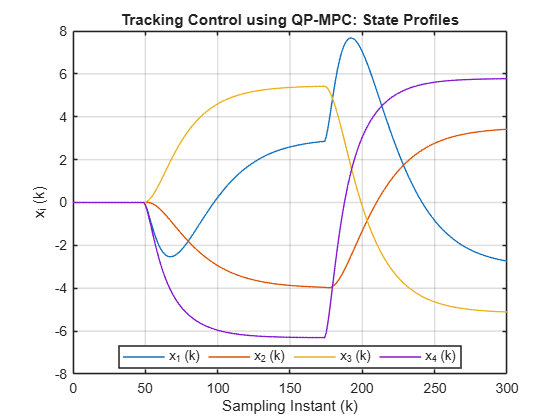

    % Controller calculations at instant k assuming state vector is
    % perfectly measured
     tic
    mpc.us_k(:,k) = inv(mpc.Gain_ss) * rk_f(:,k+1) ;
    mpc.xs_k(:,k) = inv(eye(mpc.n_st) - mpc.phy) * mpc.gam * mpc.us_k(:,k) ;
    b_vec = mpc.F_vec ;
    mpc.xk = xk(:,k) ;   % Plant state is perfectly measured 
    Fk_vec = mpc.F_mat*mpc.xk - 2 * mpc.WU_mat * mpc.Iu_mat * mpc.us_k(:,k)  - 2 * mpc.Su_mat' * mpc.WX_mat * mpc.Ix_mat * mpc.xs_k(:,k) ; 
    [Uf_k,FVAL] = quadprog(mpc.H_mat, Fk_vec, mpc.A_mat, b_vec,[],[],[],[],[],options  )  ;
    mpc.uk = Uf_k(1:n_ip) ;  % Implement only optimal u(k) 

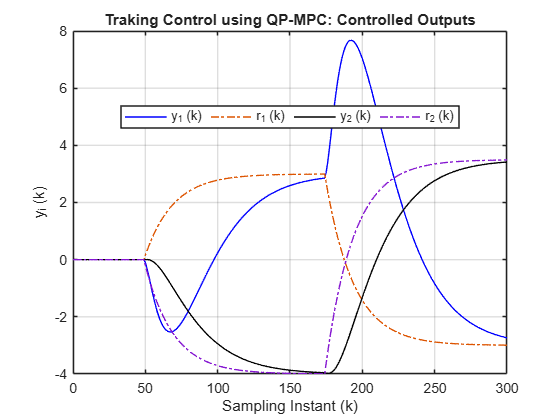

       time_log_TV(k) = toc;
    uk(:,k) = mpc.uk ;
    xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) ; 

 end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;

** Display Simulation Results **

Now observe the simulation results and note that the time varying set points are well tracked by the outputs.

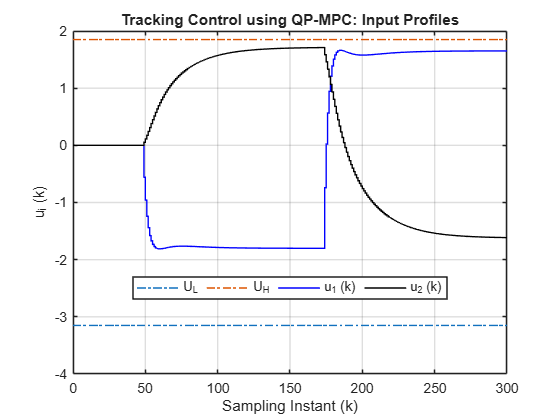

figure(4), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)', 'Orientation','horizontal','Location','Best')
title('Tracking Control using QP-MPC: State Profiles')
figure(5), plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('y_i (k)')
legend('y_1 (k)', 'r_1 (k)', 'y_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best') 

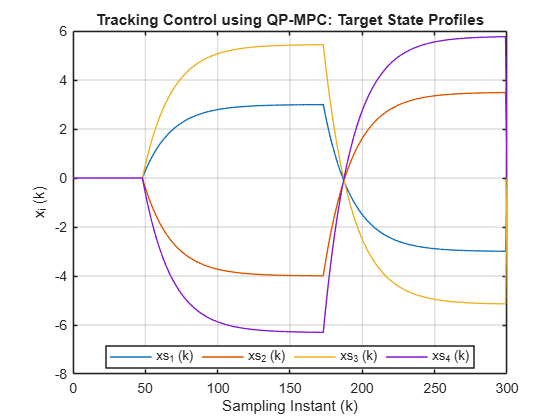

title('Traking Control using QP-MPC: Controlled Outputs')

U_mimits = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;
figure(6), stairs(kT, U_mimits, '-.', 'LineWidth',1), grid

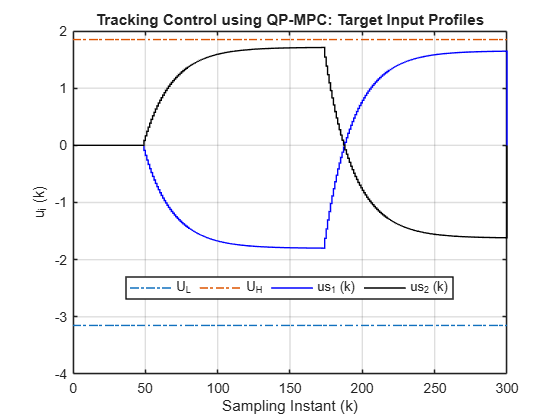

hold on 
 stairs(kT, uk(1,:)', 'b','LineWidth',1)
 stairs(kT, uk(2,:)', 'k','LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_i (k)')
title('Tracking Control using QP-MPC: Input Profiles')
legend('U_L', 'U_H', 'u_1 (k)', 'u_2 (k)','Orientation','horizontal','Location','Best')
figure(7), plot(kT, mpc.xs_k(1,:), kT, mpc.xs_k(2,:), kT, mpc.xs_k(3,:), kT, mpc.xs_k(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')

legend('xs_1 (k)', 'xs_2 (k)', 'xs_3 (k)', 'xs_4 (k)', 'Orientation','horizontal','Location','Best')
title('Tracking Control using QP-MPC: Target State Profiles')
U_mimits = [mpc.u_L(1)*ones(N,1) mpc.u_H(1)*ones(N,1)]  ;
figure(8), stairs(kT, U_mimits, '-.', 'LineWidth',1), grid
hold on 
 stairs(kT, mpc.us_k(1,:)', 'b','LineWidth',1)
 stairs(kT, mpc.us_k(2,:)', 'k','LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_i (k)')

Average computation time TVLMPC-QP: 0.0019473 s


title('Tracking Control using QP-MPC: Target Input Profiles')

TVLMPC-QP Cost Function: 50477.2425


legend('U_L', 'U_H', 'us_1 (k)', 'us_2 (k)','Orientation','horizontal','Location','Best')

**LMPC-QP Controller Performance: Time varying Setpoints**

**Task 3:** As done earlier, note down the average time required for controller implementation using QP solver,(**avg_time_TVLMPC_QP**). Also note down the cost function **(fval_TVLMPC_QP**).

fval_TVLMPC_QP = 0 ;
for k = 1:N-1
    fval_TVLMPC_QP=fval_TVLMPC_QP+ xk(:,k)' * mpc.Wx* xk(:,k) ;
    fval_TVLMPC_QP=fval_TVLMPC_QP+uk(:,k)' * mpc.Wu* uk(:,k) ;
end
avg_time_TVLMPC_QP = mean(time_log_TV);
disp(['Average computation time TVLMPC-QP: ', num2str(avg_time_TVLMPC_QP), ' s']);
disp(['TVLMPC-QP Cost Function: ', num2str(fval_TVLMPC_QP)]);

**Task 4: **Change the setpoint filter tuning parameter to say 0.5, 0.8, 0.9 and 0.98 from 0.95 and observe the effect on the controlled output and manipulated input behavior in each case. What do you observe?  

**Task 5:** Now change the operating point and again observe the results. 

## Unknown Disturbance Rejection 

So far we assumed that the state is perfectly measured and there are no unmeasured or unknown disturbances affecting the system dynamics. While this simplistic assumption helps in establishing some properties, any controller in practice has to deal with unmeasured/unknown disturbances. In addition, any MPC formulation has to deal with mismatch between the model used for predictions and the system dynamics. For example, the system/plant may evolve as 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d \;d\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)\;+v\left(k\right)
\end{array}$  ------(18) 

where $\left\lbrace d\left(k\right):k=0,1,2\ldotp \ldotp \ldotp \right\rbrace$ represents some unknown/unmeasured disturbance input influencing the system dynamics and $\left\lbrace v\left(k\right):k=0,1,2\ldotp \ldotp \ldotp \right\rbrace$ represents some unknown disturbance in the measured output. Here we relax the assumption that systems states are perfectly measured and assume that only the output signal, $y\left(k\right)$, is measured. Further, it is desired to develop a controller that maintains the measured output at a fixed setpoint, say $r$, i.e. when the plant is operating at a steady state, $y_s =r$. 

To simplify the development, let us consider the special case when $r=\bar{0}$, i.e. the regulatory control problem, and number of inputs equals the number of measurements, i.e. $l=m$. Let us further assume that we have developed an unconstrained state feedback control law, $u\left(k\right)=-G_{\textrm{MPC}} \;x\left(k\right)$, such that $\rho \left(\Phi -\Gamma G_{\textrm{MPC}} \right)<1$. In the absence of exact knowledge of $x\left(k\right)$, we can use *an**** internal model simulation ***to generate and estimate estimate, $\hat{x} \left(k\right)\;\textrm{of}\;x\left(k\right)$, as follows 

$\hat{x} \left(k+1\right)=\Phi \hat{x} \left(k\right)+\Gamma u\left(k\right)$   -------(19)

and use $\hat{x} \left(k\right)$ for the controller implementation instead of the true state $x\left(k\right)$. The disturbance term $\Gamma_d \;d\left(k\right)$ is missing in the internal model and as a consequence, $\hat{x} \left(k\right)\not= x\left(k\right)$.  This internal model is a form of a ***state observer/estimator*** and such an observer can be used when all the eigenvalues of $\Phi$ are strictly inside the unit circle.  Let us assume that we implement  $u\left(k\right)=-G_{\textrm{MPC}} \hat{x} \left(k\right)$,  where $\hat{x} \left(k\right)$is computed using (19).  As a consequence, the internal model evolves as $\hat{x} \left(k+1\right)=\left(\Phi -\Gamma G_{\textrm{MPC}} \right)\hat{x} \left(k\right)$ and this implies $\hat{x} \left(k\right)\to \bar{0} \;\textrm{as}\;k\to \infty$. Thus, the model is now controlled at the origin. But, our intention is to drive the plant state $y\left(k\right)\to \bar{0} \;\textrm{as}\;k\to \infty$ and not the model state.  What happens to the plant behavior under this control law? Let us analyze a simple situation where  $x\left(0\right)=\hat{x} \left(0\right)$ and a step change in input and output disturbance occurs at time $k=0$, i.e. $d\left(k\right)=\Delta d\;\;\textrm{and}\;\;\;v\left(k\right)=\Delta v\;\;\textrm{for}\;k\ge 0\ldotp \;$Even though both linear systems start from identical initial states, $\hat{x} \left(k\right)\;\textrm{and}\;x\left(k\right)$ evolve differently for $k\ge 0\ldotp$ Defining estimation errors $\delta x\left(k\right)=\;x\left(k\right)-\;\hat{x} \left(k\right)$ and $\delta k\left(k\right)=y\left(k\right)-\hat{y} \left(k\right)$, from (18) and (19) it follows that 

 $\delta x\left(k+1\right)=\Phi \delta x\left(k\right)+\Gamma_d \;\Delta d$ -----(20a)

$\delta y\left(k\right)=C\delta x\left(k\right)+\Delta v$ ------(20b)

At the steady state, we have 

 $\delta x_s =x_s -\hat{x_s } =x_s -\bar{0} \;={\left(I-\Phi \right)}^{-1} \Gamma_d \;\Delta d$  ------(21a)

$\begin{array}{l}
\delta y_s ={\mathrm{y}}_s -{\hat{y} }_s ={\mathrm{y}}_s =Cx_s +\Delta v\\
\;\;\;\;\;={C\left(I-\Phi \right)}^{-1} \Gamma_d \;\Delta d+\Delta v\not= \bar{0} 
\end{array}$  ------(21b)

i.e. $\hat{x} \left(k\right)\to \bar{0} \;\textrm{as}\;k\to \infty$ implies that $x\left(k\right)\to {\left(I-\Phi \right)}^{-1} \Gamma_d \;\Delta d\;\textrm{as}\;k\to \infty$. Thus, implementing $u\left(k\right)=-G_{\textrm{MPC}} \hat{x} \left(k\right)$takes $y\left(k\right)\;\to {C\left(I-\Phi \right)}^{-1} \Gamma_d \;\Delta d+\Delta v\not= \bar{0} \;\textrm{as}\;k\to \infty$, i.e. we have an offset between the desired setpoint, $r=\bar{0}$ and the controlled outputs, ${\mathrm{y}}_s$.  

    To achieve offset-free control, we use the idea of target state and target input that we have used for solving the servo control problem. But there is one difference. We now find a target state and target input for the internal model, i.e. $\left({\hat{x} }_s ,u_s \right),$  in such a way that the plant output reaches the desired output, $y_s =r$.  Note that $\left(\Delta d,\Delta v\right)$ are unknown/unmeasured signals. However, it is clear from equation (21b) that $\delta y_s ={\mathrm{y}}_s -{\hat{y} }_s$ is a measurable quantity as ${\mathrm{y}}_s$ is measured and ${\hat{y} }_s$ can be estimated using the internal model. Thus, this signal can be viewed as an ***indirect measurement*** of the unmeasured disturbance signals$\left(\Delta d,\Delta v\right)$ or the model plant mismatch (MPM). Let us denote it as, 

${\hat{d} }_s \equiv \delta y_s \;{=\;y}_s -{\hat{y} }_s$,

 i.e. an estimate of unmeasured disturbances/MPM. The internal model behavior at the steady state is given as 

${\hat{x} }_s ={\left(I-\Phi \right)}^{-1} \Gamma u_s$ ------(22a)

${\hat{y} }_s =C\;{\hat{x} }_s ={C\left(I-\Phi \right)}^{-1} \Gamma u_s$ ------(22b)

Now, using relationship ${{\hat{y} }_s =\;\mathrm{y}}_s -{\hat{d} }_s ,$ and setting ${\mathrm{y}}_s =r$, we can calculate the target input needed to take the system outputs${\;\mathrm{y}}_s$ to *r* as follows 

$u_s ={\left({C\left(I-\Phi \right)}^{-1} \Gamma \right)}^{-1} \left(r-{\hat{d} }_s \right)={\left({\mathrm{K}}_u \right)}^{-1} \left(r-{\hat{d} }_s \right)$ ------(23)

and the corresponding internal model should reach target state 

${\hat{x} }_s ={\left(I-\Phi \right)}^{-1} \Gamma u_s ={{\left(I-\Phi \right)}^{-1} \Gamma \left({\mathrm{K}}_u \right)}^{-1} \left(r-{\hat{d} }_s \right)$ ------(24)

Now, let us examine how the plant behaves under this control law at the steady state.

 $\begin{array}{l}
x_s ={\left(I-\Phi \right)}^{-1} \left(\Gamma u_s +\Gamma_d \;\Delta d\right)\\
\;\;\;={\left(I-\Phi \right)}^{-1} \left({\Gamma \left({\mathrm{K}}_u \right)}^{-1} \left(r-{\hat{d} }_s \right)+\Gamma_d \;\Delta d\right)
\end{array}$ ------(25)

and 

$\begin{array}{l}
y_s =C\;{\left(I-\Phi \right)}^{-1} \left({\Gamma \left({\mathrm{K}}_u \right)}^{-1} \left(r-{\hat{d} }_s \right)+\Gamma_d \;\Delta d\right)+\Delta v\\
\;\;\;\;\;=\left(r-{\hat{d} }_s \right)+\left(C\;{\left(I-\Phi \right)}^{-1} \Gamma_d \;\Delta d+\Delta v\right)
\end{array}$ ------(26)

From (21b), we have ${\hat{d} }_s =\left(C\;{\left(I-\Phi \right)}^{-1} \Gamma_d \;\Delta d+\Delta v\right)$ and substituting this in (26), it follows that $y_s =r$. Thus, if $\hat{x} \left(k\right)\to {\hat{x} }_s \;\;\textrm{given}\;\textrm{by}\;\left(24\right)\;\textrm{as}\;k\to \infty$ then$y\left(k\right)\to r\;\textrm{as}\;k\to \infty$ and we need to modify the unconstrained MPC implementation as follows  

$u\left(k\right)=u_s -G_{\textrm{MPC}} \left(\hat{x} \left(k\right)-{\hat{x} }_s \right)$ ------(27) 

 that drives $\hat{x} \left(k\right)\to {\hat{x} }_s \;\textrm{as}\;k\to \infty$ and $y\left(k\right)\to r\;\textrm{as}\;k\to \infty$. So the trick is to use signal MPM signal ${\hat{d} }_s \;{=\;y}_s -{\hat{y} }_s$  to compute  $\left({\hat{x} }_s ,u_s \right)$. 

    Now, what do we do when $\left(d\left(k\right),v\left(k\right)\right)$are time varying signals and the setpoint is also changing with time?  Since signal $y\left(k\right)$ is measured,  a simple approach to *estimate the current level of MPM*  is to estimate the output as 

$\hat{y} \left(k\right)=C\;\hat{x} \left(k\right)\;$ ------(28) 

and find how much it differs from $y\left(k\right)$ by finding MPM signal $\hat{d} \left(k\right)$ as 

 $\hat{d} \left(k\right)=y\left(k\right)-\hat{y} \left(k\right)=y\left(k\right)-C\;\hat{x} \left(k\right)\;$ ------(29)

which captures the effect of unmeasured disturbances and/or model-plant mismatch at instant k. In fact, $\hat{d} \left(k\right)$ can be viewed as an indirect measurement of cumulative disturbance signals generated by the difference equation governing the dynamics of the state estimation error, $\delta x\left(k\right)$, i.e. 

 $\delta x\left(k+1\right)=\Phi \delta x\left(k\right)+\Gamma_d \;d\left(k\right)$  ----(30a)

 $\hat{d} \left(k\right)=C\left(x\left(k\right)-\;\hat{x} \left(k\right)\right)+v\left(k\right)=C\delta x\left(k\right)+v\left(k\right)$  ----(30b)

To make use of this signal for incorporating feedback in the MPC formulation and to estimate the time varying target state, we  can make a simplistic assumption that $\hat{d} \left(k\right)$ remains constant over the entire prediction horizon, [k,k+p], i.e. 

$\hat{d} \left(k+j\right)=\hat{d} \left(k\right)\;\textrm{for}\;j=0,1,\ldotp \ldotp \ldotp \ldotp ,p$  ------(31)

Under this assumption, we can modify the target state calculations by using mismatch adjusted setpoint signal $\left(r\left(k\right)-\hat{d} \left(k\right)\right)$ as follows 

 $\begin{array}{l}
x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \Gamma u_s \left(k\right)\\
u_s \left(k\right)={\left(C{\left(I-\Phi \right)}^{-1} \Gamma \right)}^{-1} \;\left(r\left(k\right)-\hat{d} \left(k\right)\right)
\end{array}$ ------(32)

If signal $\hat{d} \left(k\right)$ changes abruptly or contains fluctuations due to noise in the measurements, then we can think of using a unity gain ***robustness filter ***of the form 

${\hat{d} }_f \left(k+1\right)=\Phi_d \;{\hat{d} }_f \left(k\right)+\left({I-\Phi }_d \right)\;\hat{d} \left(k\right)$  ------(33)

and use $\left(r_f \left(k\right)-\hat{d_f } \left(k\right)\right)$ instead of  $\left(r\left(k\right)-\hat{d} \left(k\right)\right)$ for target calculations.  Here $\Phi_d$  is a diagonal matrix with diagonal element $0\le \gamma_i <1\ldotp \;$ When the number of outputs equals the number of inputs and the steady state gain matrix is invertible, we can find the target states and target inputs as follows 

 $\begin{array}{l}
x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \Gamma u_s \left(k\right)\\
u_s \left(k\right)={\left(C{\left(I-\Phi \right)}^{-1} \Gamma \right)}^{-1} \;\left(r_f \left(k\right)-\hat{d_f } \left(k\right)\right)
\end{array}$ ------(34)

When $u_s \left(k\right)$ computed using (34) exceed input bounds, or when $l\not= m$, the target state can be computed by solving the following optimization problem

$\min_{u_s \left(k\right)} \left\lbrace {\left(r_f \left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r_f \left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(35)

subject to,

$y_s \left(k\right)=K_u u_s \left(k\right)+{\hat{d} }_f \left(k\right)$ ------(36) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (37)

    Introduction of an internal model for state estimation is a significant departure from the perfect state measurement based formulation used so far. Before we proceed to demonstrate effectiveness of this modification, let us summarize the steps involved in the modified MPC formulation at a k'th sampling instant 

- Step 1: Acquire measurement $y\left(k\right)$ from the plant and find the mismatch signal, $\hat{d} \left(k\right)$, using equation (29) 

- Step 2: Compute filtered model plant mismatch signal, ${\hat{d} }_f \left(k\right)$, using equation (33)

- Step 3: Compute filtered setpoint $r_f \left(k\right)$ using equation (12) 

- Step 4: Compute target states and inputs ($\left.x_s \left(k\right),u_s \left(k\right)\right)$ using either equation (34) or by solving optimization problem (35) to (37)

- Step 5: Solve the following constrained optimization problem set on the moving horizon framework


$$\;$$
  
$${\mathrm{U}}_p^* \left(k\right)=\overset{\arg \;\min }{{\mathrm{U}}_p \left(k\right)} \;\;\;\left\lbrack J\left(x\left(k\right),U_f \left(k\right)\right)\right\rbrack$$
   

$J\left\lbrack x\left(k\right),{\mathrm{U}}_p \left(k\right)\;\right\rbrack ={{\left\|z\left(k+p\right)-x_s \left(k\right)\right\|}^2 }_{W_{\infty } } +\sum_{j=0}^{p-1} \left\lbrace {{\left\|z\left(k+j\right)-x_s \left(k\right)\right\|}^2 }_{W_x } +{{\left\|u\left(k+j|k\right)-u_s \left(k\right)\right\|}^2 }_{W_u } \right\rbrace$  ------(38)

Subject To

$\begin{array}{l}
z\left(k+j+1\right)=\Phi z\left(k+j\right)+\Gamma u\left(k+j|k\right)\;\;\textrm{for}\;j=0,1,\ldotp \ldotp \ldotp ,p-1\;\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\textrm{with}\;\textrm{initial}\;\textrm{condition}\;\;z\left(k\right)=\hat{x} \left(k\right)
\end{array}$   ------(39) 

     $u_L \le u\left(k+j|k\right)\le u_H$   for$j=0,1,2,\ldotp \ldotp \ldotp \ldotp p-1$   ------(40) 

- Step 6: Set $u\left(k\right)=u^* \left(k|k\right)$ and update the internal model states using equation (19) 

- Step 7: Communicate $u\left(k\right)$ to the plant 

Note that, unlike the previous formulation, model predictions given by equation (29) are now initialized using the state of the internal model $\hat{x}$ and not the true plant state, $x\left(k\right)$. 

Let us now see how the QP-LMPC rejects the unknown disturbances. Again the steps upto steady state gain computation are same and hence omitted.

### Closed loop simulations for Q tank Process with Disturbance Rejection

 
clear all 
close all
global QTank 

Set_Graphics_Parameters ;   % This script file sets font size and line thickness for figures 

**Task 1**: Select the operating point for Q Tank process.  

operating_pt=2;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

% Initialization of linear discrete time model for plant simulation 

phy = QTank.phy ;
gam = QTank.gama_u  ;
gam_d = QTank.gama_d  ;
[n_st,n_ip] = size(gam) ;
C_mat = [ 1 0 0 0 ; 0 1 0 0] ;  % Levels are assume to be directly measured 
[n_op, nx ] = size(C_mat)  ;         
[n_st,n_ip] = size(gam) ;


We have set the simulation run time N to 500.

N = 500 ;      % Simulation run time
% Initialization of Internal model for MPC 


State weighting matrix


mpc.phy = phy ;   
mpc.gam = gam ; 

Input weighting matrix


mpc.C_mat = C_mat ; 
[mpc.n_st,mpc.n_ip] = size(mpc.gam) ;

mpc = struct with fields:
       phy: [4×4 double]
       gam: [4×2 double]
     C_mat: [2×4 double]
      n_st: 4
      n_ip: 2
      n_op: 2
    n_pred: 50
        Wx: [4×4 double]
        Wu: [2×2 double]


[mpc.n_op, nx] = size(mpc.C_mat) ; 

**MPC Tuning Parameters**

We have set the prediction horizon n_pred to 50**.**

mpc.n_pred =50; 

 We have created variables ${\textrm{mpc}\ldotp W}_x$, the **State Weighting Matrix  **and ${\textrm{mpc}\ldotp W}_u$, the **Input Weighting Matrix**.  

 $W_x =\left\lbrack \begin{array}{cccc}
\alpha_1  & 0 & 0 & 0\\
0 & \alpha_2  & 0 & 0\\
0 & 0 & \alpha_3  & 0\\
0 & 0 & 0 & \alpha_4 
\end{array}\right\rbrack$  and  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$

Do not alter them.

alpha(1) =2;  alpha(2) = 10;
alpha(3) =2;  alpha(4) = 2; 
disp('State weighting matrix')
mpc.Wx= diag(alpha );
disp('Input weighting matrix')
beta(1) =2;  beta(2) =1;
mpc.Wu= diag(beta) 

For the quadruple tank system input voltages are bound between 0 and 5 Volts. Thus, bounds on perturbation inputs, with reference to $U_s ={\left\lbrack \begin{array}{cc}
3 & 3
\end{array}\right\rbrack }^T$can be defined as follows 

$u_H =\left\lbrack \begin{array}{c}
5\\
5
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
2\\
2
\end{array}\right\rbrack \;$  and  $u_L =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
3\\
3
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-3\\
-3
\end{array}\right\rbrack$

We have written a code that  generates matrices needed for specifying input constraints.  

mpc.u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
mpc.u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] 
mpc.deluL = [] ; mpc.deluH = [] ; 

**Generation of  QP matrices**

Note: A function (Gen_QP_Matrices_Tracking) is used to generate QP matrices.

% Generate QP matrices. Note: Program developed in Lesson 6 of Module 3 is made into a function 

[mpc] = Gen_QP_Matrices_Tracking( mpc ) ;


**Closed loop simulations using QP-LMPC under ideal conditions**

Set-point filter parameter is fixed to 0.95.

rk_f = zeros(n_op,N);     % Setpoint filter parameters 
beta_r=0.95;
phy_r = beta_r * eye(n_op) ; % Setpoint filter matrix 
mpc.xs_k = zeros(mpc.n_st,N);
mpc.us_k = zeros(n_ip,N) ;
mpc.xkhat = zeros(mpc.n_st,N);
mpc.yhat = zeros(n_op,N) ; 
mpc.dkhat = zeros(n_op,N); % Model plant mismatch signal 
mpc.dkhat_f = zeros(n_op,N); % Filtered Model plant mismatch signal 

**Task 2: **Let us now observe the effect of disturbance filter on the servo response of the controller. Set the filter parameter $\beta_d$ to 0.9.

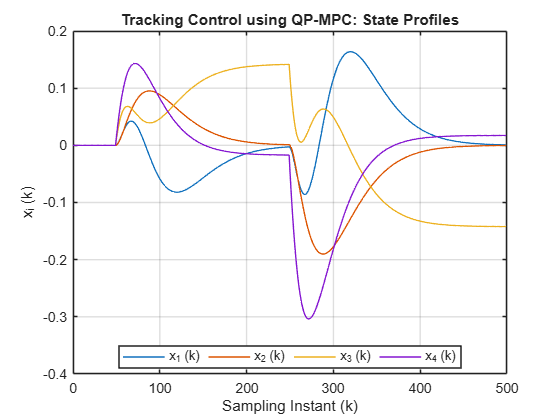

beta_d=0.9;
mpc.phy_d = beta_d * eye(n_op) ;   % Disturbance filter 

time_log_DR =zeros(N,1);
% Matrices for simulating system dynamics 
xk = zeros(n_st,N);
uk = zeros(n_ip,N) ;
yk = zeros(n_op,N);
yk(:,1) = C_mat * xk(:,1) ; 
dk = zeros(1,N) ;
rk = [0 0]';
gam_d=QTank.gama_d;
% Disturbance input 
for k = 1:N
    if ( k < 50 )
        dk(k) = 0 ;
    elseif (k >= 50 ) && (k < 250)
        dk(k) = 0.2 ;  % Introduce disturbance change at k = 50
    else
        dk(k) = -0.2 ;  % Introduce another disturbance change at k = 250
    end
end

% Closed loop simulations using QP-LMPC under model-plant mismatch 
options=optimoptions('quadprog', 'display', 'off');

MPM_copensation = 1;

for k = 1:N-1
    kT(k) = (k-1);

    rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ; 

    % Controller calculations at instant k under unmeasured disturbance
tic
    % Estimate model plant mismatch and filter it using unity gain filter 
    mpc.yhatk(:,k) = mpc.C_mat * mpc.xkhat(:,k) ; 
    mpc.dkhat(:,k) = yk(:,k) - mpc.yhatk(:,k) ;  
    mpc.dkhat_f(:,k+1) = mpc.phy_d * mpc.dkhat_f(:,k) + (eye(n_op) - mpc.phy_d) * mpc.dkhat(:,k) ; 
  
    % Find target state and target input using model plant mismatch signal 
    if (MPM_copensation == 1)
        mpc.us_k(:,k) = inv(mpc.Gain_ss) * ( rk_f(:,k+1) - mpc.dkhat_f(:,k+1) )  ;
    else
        mpc.us_k(:,k) = inv(mpc.Gain_ss) * ( rk_f(:,k+1)  )  ;
    end
    mpc.xs_k(:,k) = inv(eye(mpc.n_st) - mpc.phy) * mpc.gam * mpc.us_k(:,k) ;

    b_vec = mpc.F_vec ;   
    Fk_vec = mpc.F_mat*mpc.xkhat(:,k) - 2 * mpc.WU_mat * mpc.Iu_mat * mpc.us_k(:,k) ... 
             - 2 * mpc.Su_mat' * mpc.WX_mat * mpc.Ix_mat * mpc.xs_k(:,k) ; 
    [Uf_k,FVAL] = quadprog(mpc.H_mat, Fk_vec, mpc.A_mat, b_vec,[],[],[],[],[],options  )  ;
    mpc.uk = Uf_k(1:n_ip) ;  % Implement only optimal u(k) 

    % Internal MPC model update from k to k+1
     mpc.xkhat(:,k+1) = mpc.phy * mpc.xkhat(:,k) + mpc.gam * mpc.uk  ;
 time_log_DR(k)=toc;
    % Quadruple tank Plant Simulation from k to k+1 using discrete linear model 
    uk(:,k) = mpc.uk ;
    xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
    yk(:,k+1) = C_mat * xk(:,k+1) ; 
 end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ;
mpc.dkhat(:,N) = mpc.dkhat(:,N-1) ; 
mpc.us_k(:,N) = mpc.us_k(:,N-1) ;
mpc.xs_k(:,N) = mpc.xs_k(:,N-1) ;

% Display simulation results 

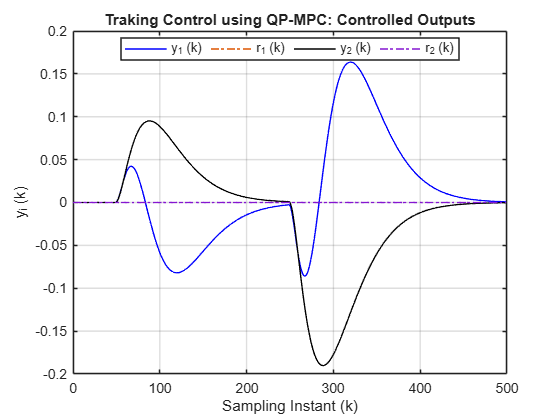


figure(9), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)', 'Orientation','horizontal','Location','Best')
title('Tracking Control using QP-MPC: State Profiles')

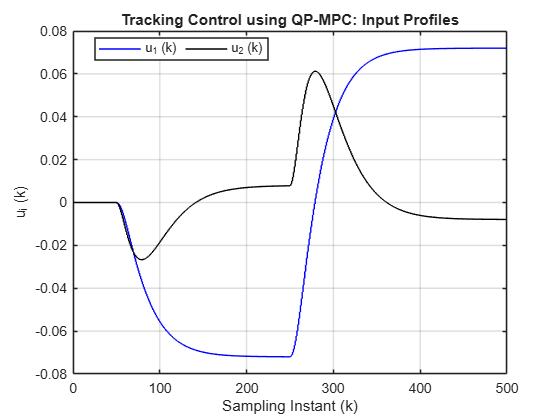


figure(10), plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('y_i (k)')
legend('y_1 (k)', 'r_1 (k)', 'y_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best') 
title('Traking Control using QP-MPC: Controlled Outputs')

figure(11),  stairs(kT, uk(1,:)', 'b','LineWidth',1),  grid
hold on 

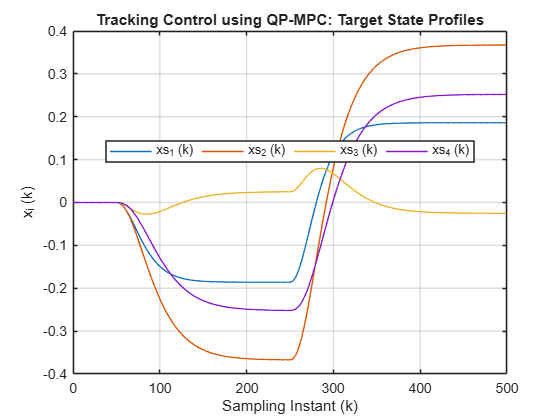

stairs(kT, uk(2,:)', 'k','LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_i (k)')
title('Tracking Control using QP-MPC: Input Profiles')
legend( 'u_1 (k)', 'u_2 (k)','Orientation','horizontal','Location','Best')

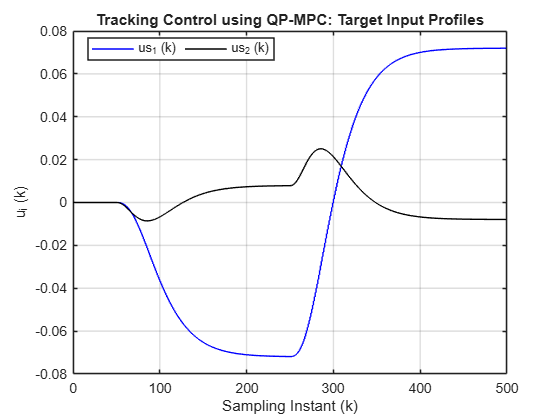


figure(12), plot(kT, mpc.xs_k(1,:), kT, mpc.xs_k(2,:), kT, mpc.xs_k(3,:), kT, mpc.xs_k(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('xs_1 (k)', 'xs_2 (k)', 'xs_3 (k)', 'xs_4 (k)', 'Orientation','horizontal','Location','Best')
title('Tracking Control using QP-MPC: Target State Profiles')

figure(13), stairs(kT, mpc.us_k(1,:)', 'b','LineWidth',1), grid
hold on 

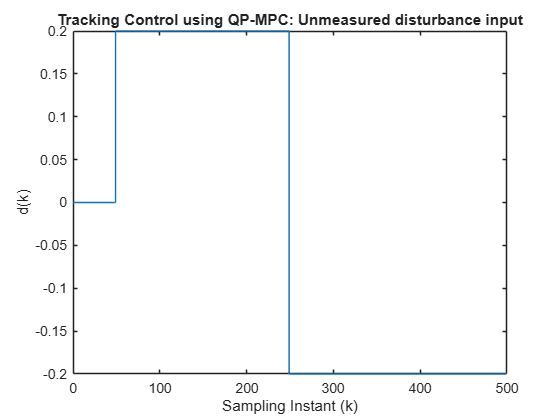

stairs(kT, mpc.us_k(2,:)', 'k','LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_i (k)')

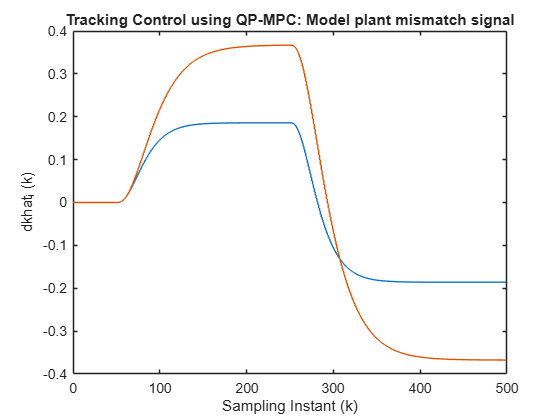

title('Tracking Control using QP-MPC: Target Input Profiles')
legend( 'us_1 (k)', 'us_2 (k)','Orientation','horizontal','Location','Best')
figure(14), stairs( kT, dk,'LineWidth',1 )
xlabel('Sampling Instant (k)'), ylabel('d(k)')

title('Tracking Control using QP-MPC: Unmeasured disturbance input')

figure(15), stairs( kT, mpc.dkhat_f','LineWidth',1 )
xlabel('Sampling Instant (k)'), ylabel('dkhat_i (k)')
title('Tracking Control using QP-MPC: Model plant mismatch signal')

**LMPC-QP Controller Performance: Disturbance Rejection**

**Task 3:** Note down the average time required for controller implementation using QP solver,(avg_time_DRLMPC_QP). Also note down the cost function (fval_DRLMPC_QP). The PI is now calculated using the estimated states

fval_DRLMPC_QP = 0 ;
for k = 1:N-1

Average computation time DRLMPC-QP: 0.0016681 s


    fval_DRLMPC_QP=fval_DRLMPC_QP+ mpc.xkhat(:,k)' * mpc.Wx* mpc.xkhat(:,k) ;

DRLMPC-QP Cost Function: 487.2721


   fval_DRLMPC_QP=fval_DRLMPC_QP+uk(:,k)' * mpc.Wu* uk(:,k) ;
end
avg_time_DRLMPC_QP= mean(time_log_DR);
disp(['Average computation time DRLMPC-QP: ', num2str(avg_time_DRLMPC_QP), ' s']);
disp(['DRLMPC-QP Cost Function: ', num2str(fval_DRLMPC_QP)]);

**Task 4: **Change the disturbance filter tuning parameterr to say 0, 0.5, 0.8, 0.85, and 0.95 from 0.9 and observe the effect on the controlled output and manipulated input behavior in each case. What do you observe?  

**Task 5:** Now change the operating point and again observe the results. 

## Conclusions

In this lesson, we have made two major modifications in the vanilla regulatory MPC formation developed in the previous lesson: (i) incorporation of setpoint /reference tracking or servo capabilities and (ii) ability to handle unknown disturbance and/or model-plant mismatch( MPM). Unity gain setpoint filter and unity gain mismatch signal filter are two additional parameters introduced to for shaping the closed loop servo response and improve robustness in the face of MPM. The resulting MPC scheme can be viewed as a vanilla MPC scheme that can be used in any practical application. The MPM/disturbance handling mechanism introduced here is quite naive though it helps in offset removal. Moreover, we have introduced an internal dynamic model for MPC that reconstructs the state sequence and uses the estimated states for control rather than the measured of true states. However, the proposed approach works only for open loop stable systems and requires further modifications to deal with marginally stable or unstable systems. 

## Appendix: Discrete Time Unity Gain Filter 

Consider a unity gain 1′st order transfer function, used for filtering a signal $y\left(t\right)$ to generate $y_f \left(t\right)$


$$y_f \left(s\right)=\frac{1}{1+\tau_f s}y\left(s\right)$$


which is equivalent to ODE-IVP  


$$\tau_f \frac{dy_f }{\textrm{dt}}+y_f \left(t\right)=y\left(t\right)\;\;\;\textrm{with}\;y_f \left(0\right)=0$$
  

In discrete time (with sampling interval $T$), this ODE-IVP is equivalent to linear difference equation 


$$y_f \left(k+1\right)=\alpha y_f \left(k\right)+\left(1-\alpha \right)y\left(k\right)\;\textrm{with}\;\;y\left(0\right)=0$$
  

where $\alpha =\exp \left(\frac{-T}{\tau_f }\right)$. Note that $0<\alpha <1$  for any  $\tau_f <0$ Or in time domain. The filter is often implemented by removing the unit delay, i.e.


$$y_f \left(k\right)=\alpha y_f \left(k-1\right)+\left(1-\alpha \right)y\left(k\right)$$


Now, consider scenario when there are multiple noisy signals filtered through unity gain filters  


$$y_{1,f} \left(k\right)=\alpha_1 y_{1,f} \left(k-1\right)+\left(1-\alpha_1 \right)y_1 \left(k\right)$$



$$\begin{array}{l}
y_{2,f} \left(k\right)=\alpha_2 y_{2,f} \left(k-1\right)+\left(1-\alpha_2 \right)y_2 \left(k\right)\\
\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp =\;\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp 
\end{array}$$



$$y_{r,f} \left(k\right)=\alpha_r y_{r,f} \left(k-1\right)+\left(1-\alpha_r \right)y_r \left(k\right)$$


The above equations can be combined into a single matrix equation as follows 


$$y_f \left(k\right)=\Phi_f y_f \left(k-1\right)+\left(I-\Phi_f \right)y\left(k\right)$$



$$\Phi_f =\left\lbrack \begin{array}{cccc}
\alpha_1  & 0 & \ldotp \ldotp \ldotp  & 0\\
0 & \alpha_2  & \ldotp \ldotp \ldotp  & 0\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
0 & 0 & \ldotp \ldotp \ldotp  & \alpha_r 
\end{array}\right\rbrack$$


Typical values of $\alpha_i$ are chosen in range $0\ldotp 9\le \alpha_i <0\ldotp 99$. Choosing $\alpha_i =0$ sets $y_{i,f} \left(k\right)=y_i \left(k\right)$ and the filtering is eliminated. 